# Graph generation

Set default values for all succeding graphs.

addpath(genpath(pwd+"\extensions"))

addpath functions
setDefaults();

We want to generate random graphs with specific properties.

## Random graphs

Let's first generate a graph with given #nodes and #edges, no self loops and graph connected.

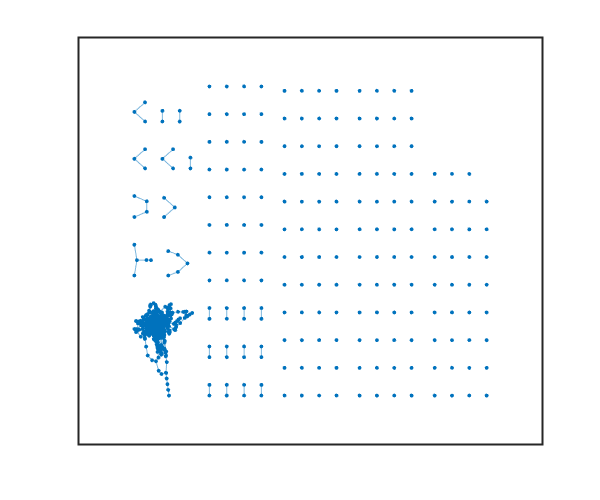

% set options to be able to recompute
seed = 1409;
rng(seed)
n = 1000;
e = 1000;

% generate graph with n nodes and e edges
adj = spalloc(n, n, e);
idx = randperm(n * n, e+n);
idx(ismember(idx, 1:n+1:n*n)) = [];
idx = idx(1:e);
% adjacency matrix
adj(idx) = 1;
adj = min( adj + adj.', 1);
adj = full(adj);
% heatmap(matrix)
% heatmap(triu(matrix))
% Deg=sum(matrix)
G = graph(adj);

% get the biggest connected component of G
[bin,binsize] = conncomp(G);%,'Type','weak');
idx = binsize(bin) == max(binsize);
SG = subgraph(G, idx);

% plot the new subgraph
plot(G)

a = plot(SG)

a =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [1×781 double]
         YData: [1×781 double]
         ZData: [1×781 double]

  Show all properties


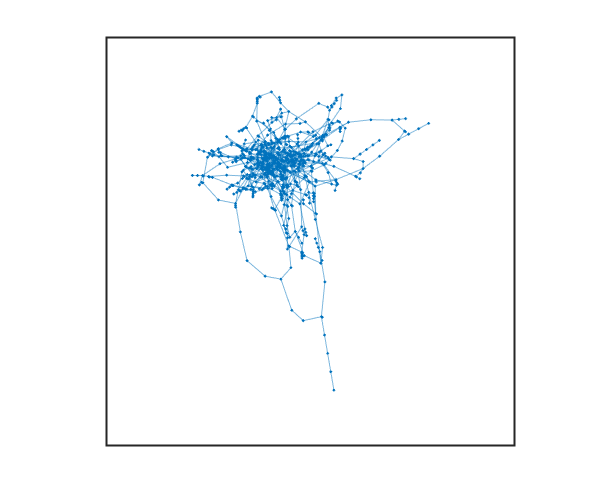

setOptionsGraph(a)

gr = plot(SG,"Layout","subspace");
setOptionsGraph(gr)

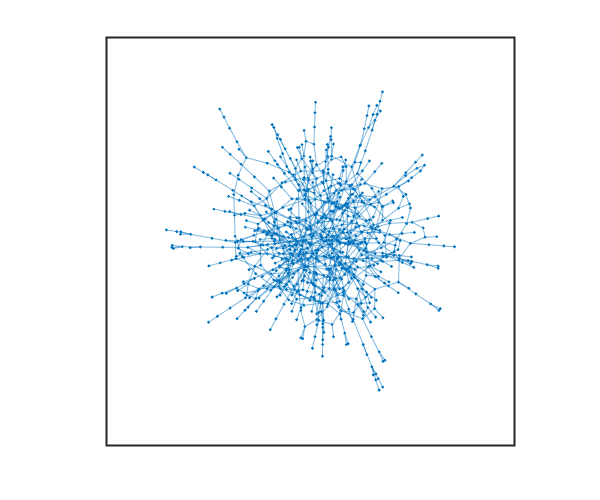

% class(gr)
embedding1 = [gr.XData' gr.YData'];
gr = plot(SG,"Layout","force","Iterations",50);
setOptionsGraph(gr)

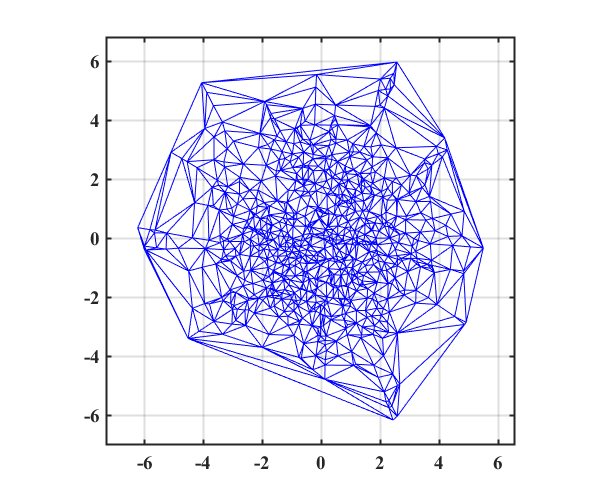

embedding2 = [gr.XData' gr.YData'];
% plot(embedding2(:,1),embedding2(:,2),"xr")
h = triplot(delaunayTriangulation(embedding2));
setOptionsGraph(h)

## Planar graphs

Generating **planar** graphs can be done by means of Delaunay triangulation with running time O(n * log(n)). For not to have only triangle faces, we exclude a subset of edges and find the biggest remaining component (see function **generateGraphs()**).

% generateGraphs(0.7,50);

% generateGraphsSucc();
% generateGraphsSucc(50);
% generateGraphsSucc(50,1722);
% generateGraphsSucc(500);
% generateGraphsSucc(500,1092);
% generateGraphsSucc(5000);
% generateGraphsSucc(5000,1882);

Here we try to compare the **Delaunay **and the **Chrobak-Payne **drawings, both with straight lines and planar graphs given.

[A,emb] = generateGraphs(0.0,10,"OnlyDelaunay",true);
% [A,xy] = grid_graph(6,5);
X = chrobak_payne_straight_line_drawing(A);

% gplot(A,X,'.-'); hold on; 
% gplot(A,emb,'r.-'); hold off

% figure
% triplot(delaunayTriangulation(X)); hold on
% gplot(A,emb,'r.-'); hold off

% figure
% triplot(delaunayTriangulation(X)); hold on
% gplot(A,X,'r.-'); hold off

## Test generated graphs

Let's read the generated graphs and display them.

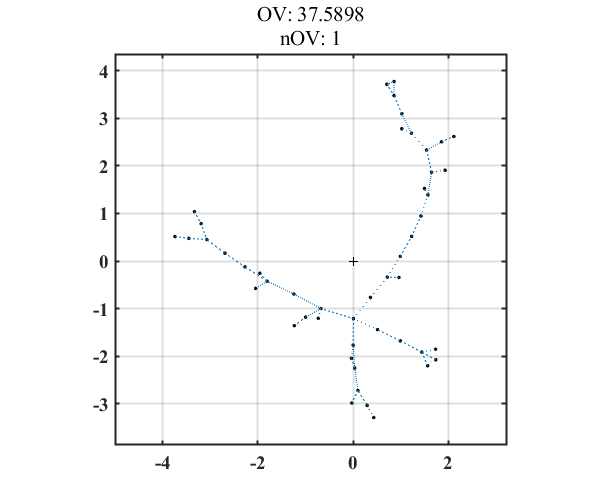

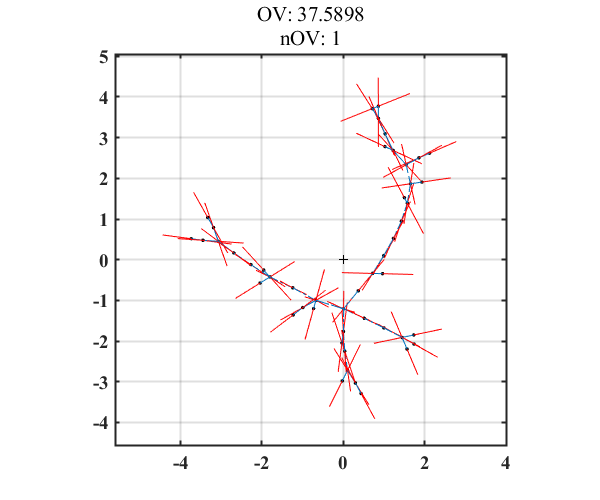

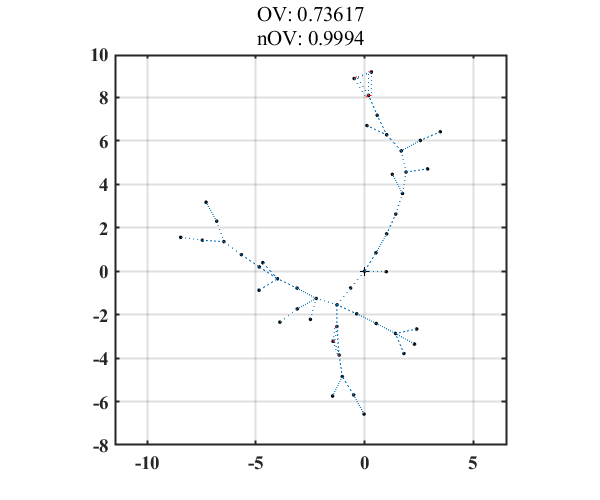

% plotCompareFour("mcs\50_1409\0.7_force50");
% plotCompareFour("mcs\500_1409\0.7_force50");
% p = plotData("mcs\50_1409\0.7_force50","Connections",true,"Nodes",true,"Embedding",false,"Difference",true);
plotCompareFour("mcs\5000_1409\0.5_force50");

## Functions

Generate the graphs with successive rates in deletion (from 0.1 to 0.9)

function generateGraphsSucc(n,seed)
    arguments
        n (1,1) {mustBeInteger,mustBePositive} = 1000
        seed (1,1) {mustBeNumeric} = 1409 %392
    end
    
    generateGraphs(0.1,n,seed,"PlotAll",true);
    for i = 0.2:0.1:0.9
        generateGraphs(i,n,seed);
    end
end

function plotCompareFour(path)
    mkdir("plots\" + path + "\")
    figure
    p = plotData(path,"Connections",true,"Nodes",true,"Embedding",false,"Difference",true);
    setOptionsGraph(p)
    exportgraphics(gcf,append("plots\" + path + "\given.png"),"Resolution",400);
    figure
    p = plotData(path,"Connections",true,"Nodes",true,"Embedding",false,"Difference",true,"Normalized",true);
    setOptionsGraph(p)
    exportgraphics(gcf,append("plots\" + path + "\givenN.png"),"Resolution",400);
    figure
    p = plotData(path,"Connections",true,"Nodes",true,"Embedding",true,"Difference",true);
    setOptionsGraph(p)
    exportgraphics(gcf,append("plots\" + path + "\emb.png"),"Resolution",400);
    figure
    p = plotData(path,"Connections",true,"Nodes",true,"Embedding",true,"Difference",true,"Normalized",true);
    setOptionsGraph(p)
    exportgraphics(gcf,append("plots\" + path + "\embN.png"),"Resolution",400);
end